clear;
clc;
T = 5; % s
Pi = [0.4500, 0, 0.4900]' %m

Pi =     0.4500
         0
    0.4900


Pf = [0, 0.4500, 0.0200]' %m

Pf =          0
    0.4500
    0.0200


syms t

function coefficients = cubicSpline(T, Pf, Pi)
        function a_axis = Path_axis(start_pos_axis, end_pos_axis, time)
            desired = [start_pos_axis;
                        0;
                        end_pos_axis;
                        0];
            known_matrix = [1 0 0 0;
                            0 1 0 0;
                            1 time time^2 time^3;
                            0 1 2*time 3*time^2];
            a_axis = inv(known_matrix)* desired;
        end

    x = Path_axis(Pi(1),Pf(1),T);
    y = Path_axis(Pi(2),Pf(2),T);
    z = Path_axis(Pi(3),Pf(3),T);
    coefficients = [x';y';z'];
end

a = cubicSpline(T, Pf, Pi)

a =     0.4500         0   -0.0540    0.0072
         0         0    0.0540   -0.0072
    0.4900         0   -0.0564    0.0075


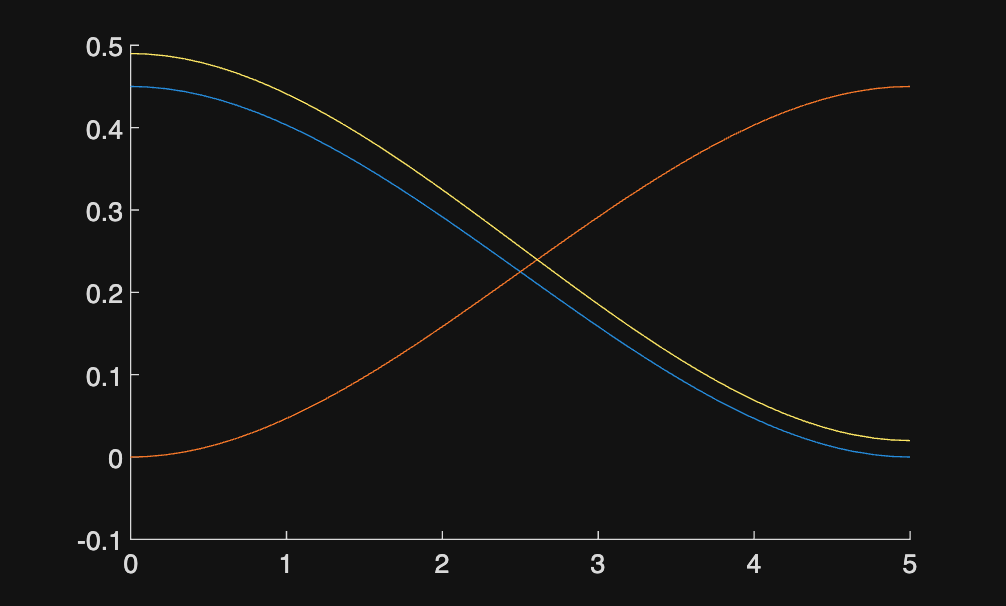



figure 
hold on;
fplot(a(1,1) + a(1,2)*t + a(1,3)*t^2 + a(1,4)*t^3, [0, T])
fplot(a(2,1) + a(2,2)*t + a(2,3)*t^2 + a(2,4)*t^3, [0, T])
fplot(a(3,1) + a(3,2)*t + a(3,3)*t^2 + a(3,4)*t^3, [0, T])
hold off;